data = load('ex2data2.txt');
X = data(:,[1:2]);
y = data(:,3);

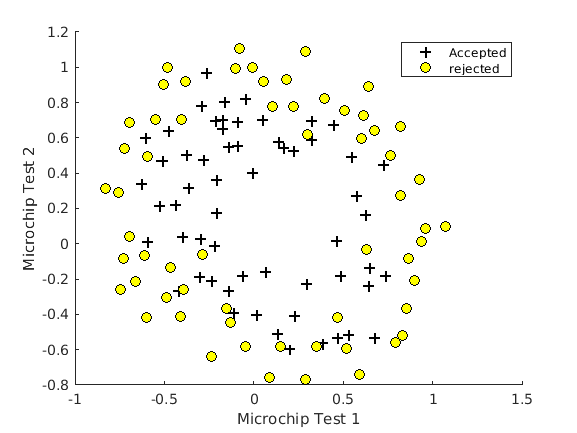

%plot the data to visualize it
plotData(X,y)%plotData is the function created in plotData.m
hold on;
%label the plot and set legends

xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
legend('Accepted' , 'rejected')
hold off


%Add additional features it also adds ones column to handle intercepts
X = mapFeature(X(:,1),X(:,2));
%applying cost function
%initializing the theta parameters
initial_theta = zeros(size(X,2),1);
size(X,2)

ans = 28

%set regularization parameter to 1
lambda = 1;
%run the costFunction
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);


%initial_theta = zeros(size(X,2),1);
lambda = 1

lambda = 1


%Running fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);
%Optimising
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


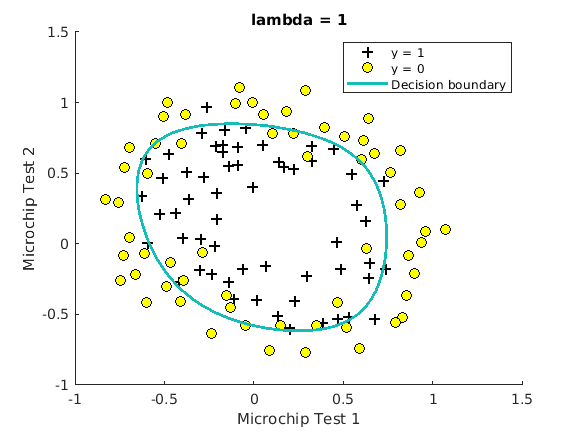

%plotting descision boundary around the datasets
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


%computing accuracy on our training set 
p = predict(theta,X);
mean(double(p == y)) * 100 %around 83percent accuracy

ans = 83.0508